# 11.20 - Numerical Differentiation

## Tangent Differentiation

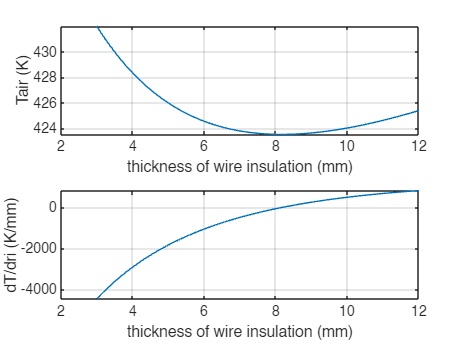

q = 75; rw = 6e-3; k  = 0.17; h = 12; Tair = 293;
T = @(ri) Tair + q/(2*pi)*(1/k*log((rw+ri)/rw)+1/h*1./(rw+ri));

% graph temperature of wire versus insulation thickness
subplot(2,1,1)
riplot = linspace(rw/2,2*rw); Tplot=T(riplot);
ri_mm = riplot*1e3;
plot(ri_mm,Tplot), grid
xlabel('thickness of wire insulation (mm)'), ylabel('Tair (K)')

% compute dT/dri with tangent line differentiation
delta=sqrt(eps);
dT_dri=(T(riplot+delta*riplot)-T(riplot))./(delta*riplot);

% graph dT/dri versus insulation thickness
subplot(2,1,2)
plot(ri_mm,dT_dri), grid
xlabel('thickness of wire insulation (mm)')
ylabel('dT/dri (K/mm)')

% get exact location and minimum temperature using fminbnd
[rimin Tmin] = fminbnd(T,rw/2,2*rw);
rimin = rimin*1e3, Tmin

rimin =    8.165206075871181


Tmin =      4.235397496131059e+02


ans =     14


% min temp happens at deriv = 0 -> need insulat thickness = 8ish mm

## Polynomial Regression

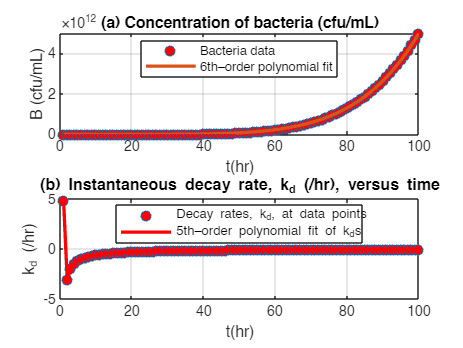

ans =     21


t = 1:100; B = 5*t.^6+20./cos(t);
[p6] = polyfit(t, B, 6);
f = polyval(p6,t);

subplot(2,1,1)
plot(t,B,'o','MarkerFaceColor','r'), hold on
plot(t,f,'LineWidth',2), grid, hold off
ylabel('B (cfu/mL)'),xlabel('t(hr)')
legend('Bacteria data','6th–order polynomial fit','location','best')
title('(a) Concentration of bacteria (cfu/mL)')

subplot(2,1,2)
p5 = -polyder(p6); % deriv, 5th order polynomial
dp5 = polyval(p5,t)./f;
tplot=(min(t):max(t));
Bval = polyval(p6,tplot);
dB=polyval(p5,tplot)./Bval;

plot(t,dp5,'o','MarkerFaceColor','r'), hold on
plot(tplot,dB,'r','LineWidth',2),grid, hold off
ylabel('k_d (/hr)'),xlabel('t(hr)')
legend('Decay rates, k_d, at data points',...
'5th–order polynomial fit of k_ds','location','best')
title('(b) Instantaneous decay rate, k_d (/hr), versus time')

## CSAPS

% need the add on

clear, clc, clf
year = 1:50; TPdata = sqrt(year).*cos(year);
p = 0.4;

sp = csaps(year,TPdata,p); % smoothing spline fit

csaps requires Curve Fitting Toolbox.


% estimation of derivative with tangent method
delta=1e-6; yearm=year-delta; yearp=year+delta;
del=yearp-yearm;
valuesm = csaps(year,TPdata,p,yearm);
valuesp = csaps(year,TPdata,p,yearp);

% calculation of instantaneous rate of change
dTPdt=(valuesp-valuesm)./del;

% generation of plots
subplot(2,1,1)
fnplt(sp,'r'); hold on
plot(year,TPdata,'ko','MarkerFaceColor','k');
hold off
title('(a) Lake Ontario Total Phosphorus Data (1967–2008)');
ylabel('TP (\mugP/L)')
subplot(2,1,2)
plot(year,dTPdt,'r','LineWidth',2), grid
title('(b) Rate of change of TP concentration, (\mugP/L)/year');
xlabel('Year'),ylabel('dTP/dt, (\mugP/L)/yr')

## Diff and gradient

% have matlab give example
diff(x)
diff(y)./diff(x)
fx = gradient(f, h)
[fx, fy] = gradient(f, h)
contour(x, y, z)
quiver(x, y, fx, fy)